## **Driver test program to check Clothoids library**

**Biarcs**

Compute distance from a point and a biarc 

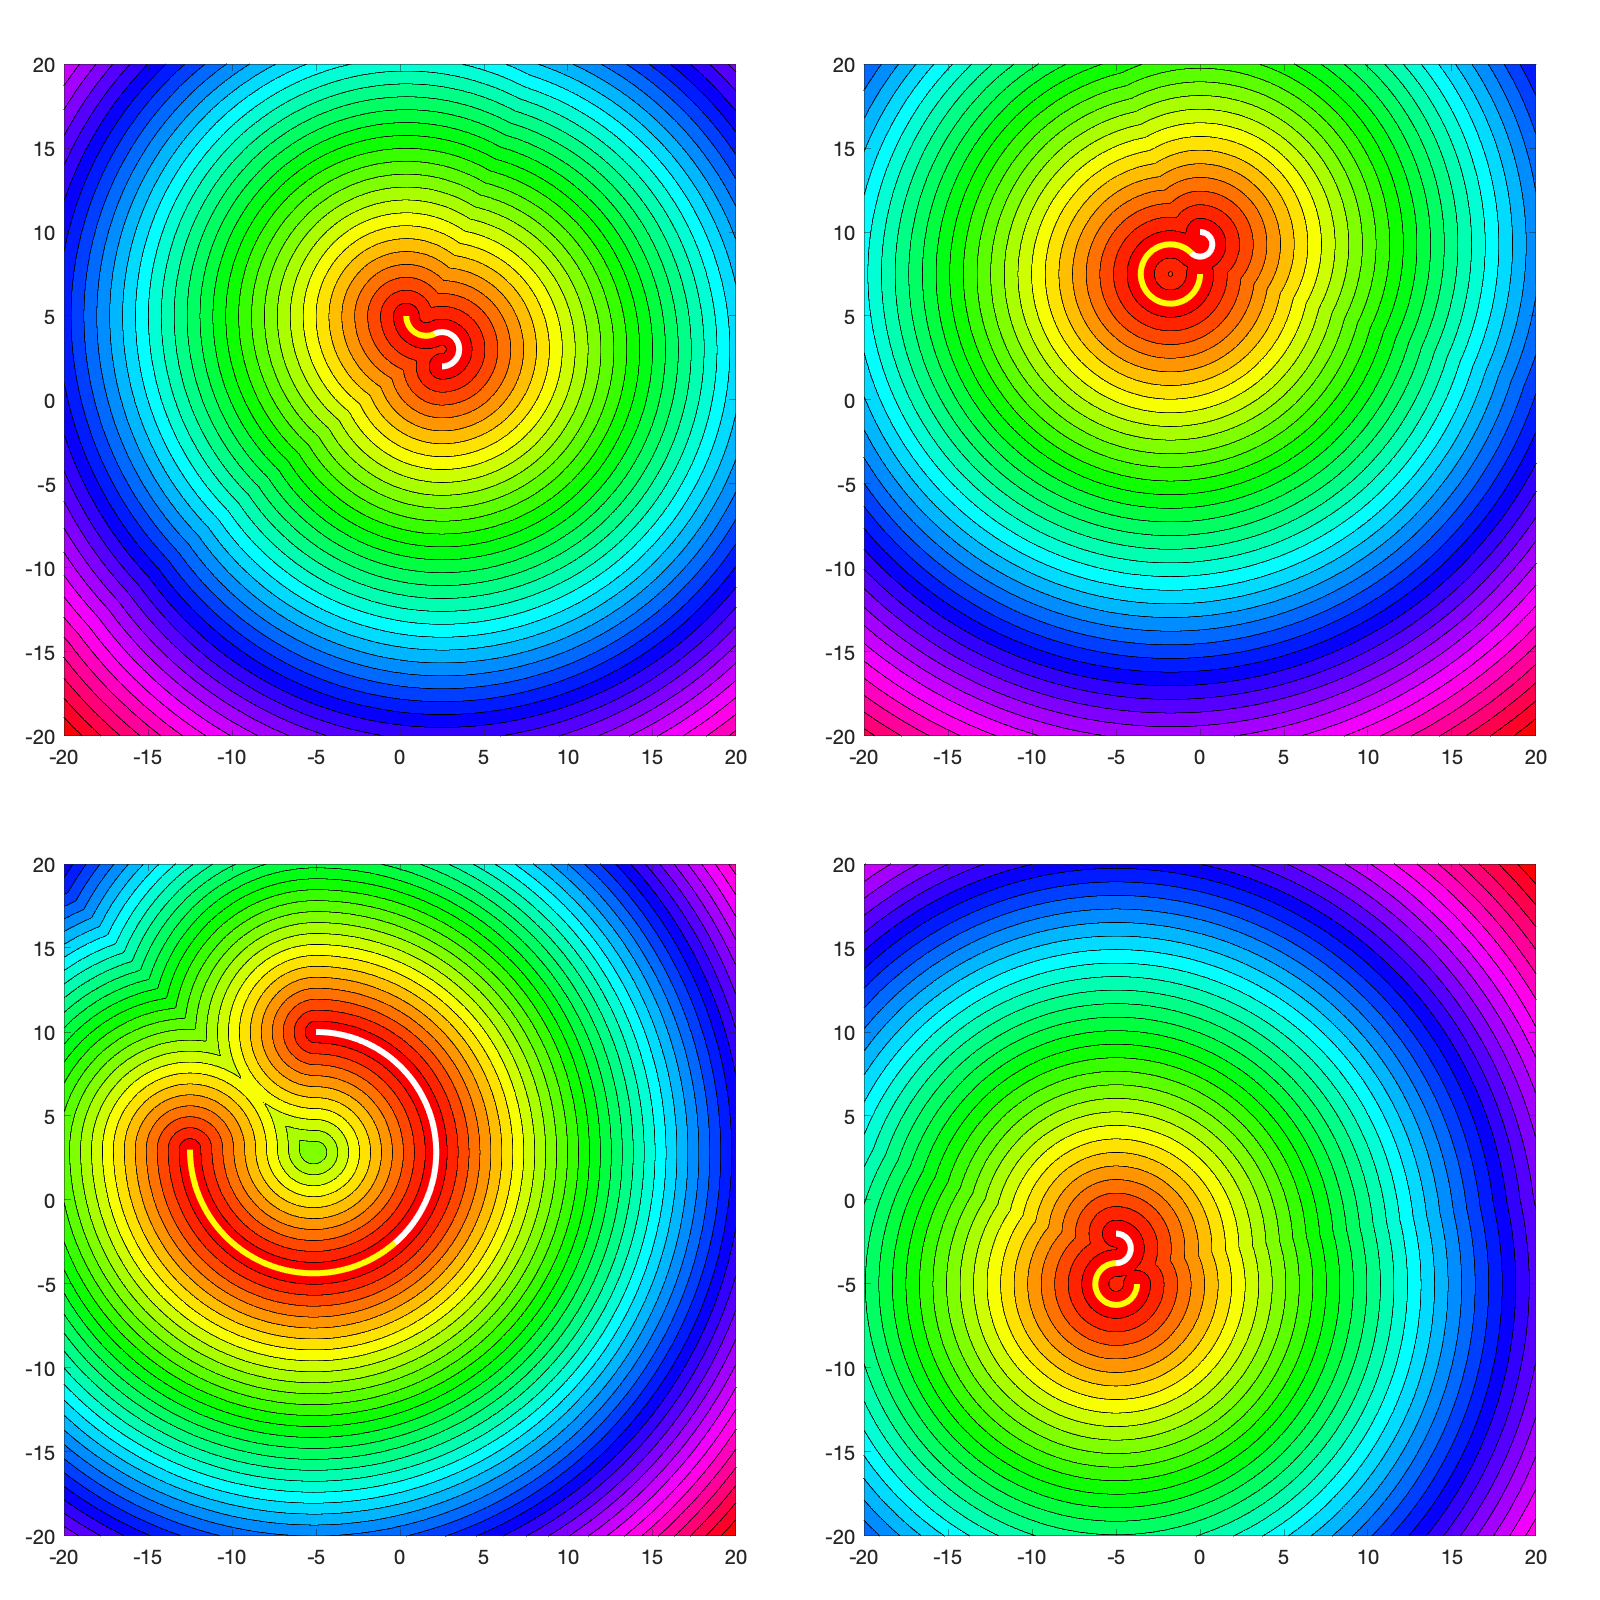

Elapsed time is 0.046475 seconds.


Elapsed time is 0.040010 seconds.


Elapsed time is 0.046683 seconds.


Elapsed time is 0.038039 seconds.


close all;

% check constructors
x0     = [-5,-5,0,2.5];
y0     = [10,-2,10,2];
theta0 = 0;
x1     = [-50,-15,0.01,1.5]/4;
y1     = [12,-20,30,20]/4;
theta1 = pi/2;

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end
  
  L1 = Biarc( x0(kk), y0(kk), theta0, x1(kk), y1(kk), theta1 );
  %
  x     = -20:0.1:20;
  y     = -20:0.1:20;
  [X,Y] = meshgrid(x,y);

  tic
  Z = L1.distance(X,Y);
  toc

  colormap(hsv);
  contourf(X,Y,Z,40);
  %surf(X,Y,Z)
  axis equal;

  hold on;
  fmt1 = {'Color','white','LineWidth',3};
  fmt2 = {'Color','yellow','LineWidth',3};
  L1.plot(1000,fmt1,fmt2);

  %
  L1.delete();
end